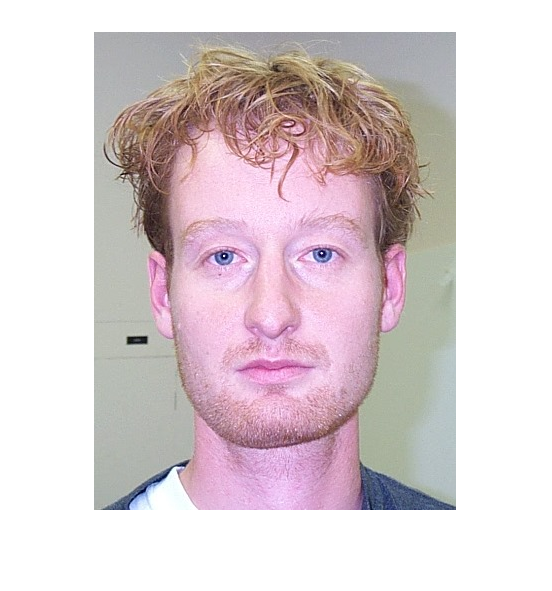

image = im2double(imread("../DB1/db1_10.jpg"));

imshow(image);

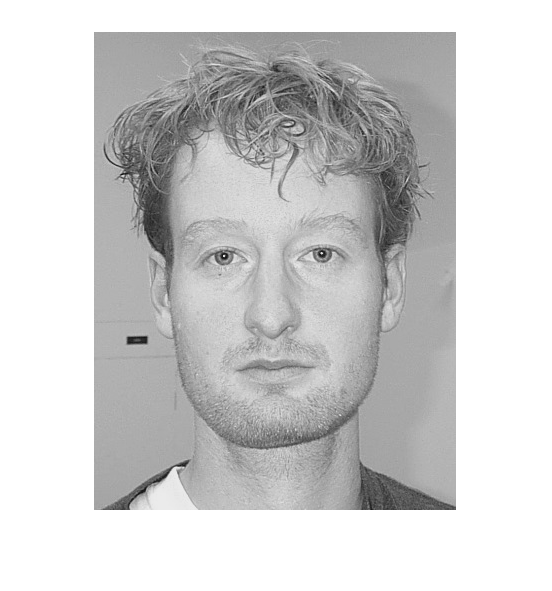


%transform to YCbCr color space 
chroma_img = rgb2ycbcr(image);

Y = chroma_img(:,:,1);
Cb = chroma_img(:,:,2) * 255;
Cr = chroma_img(:,:,3) * 255;
Cr_c = 255 - Cr; %complement of Cr

imshow(Y);

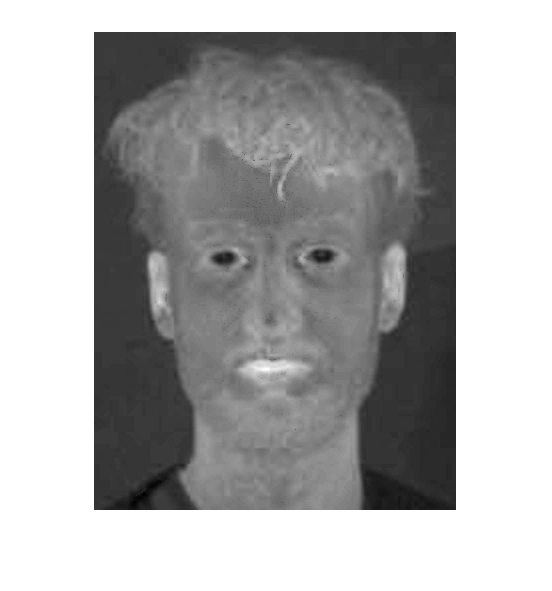

imshow(Cr.*Cr, []);

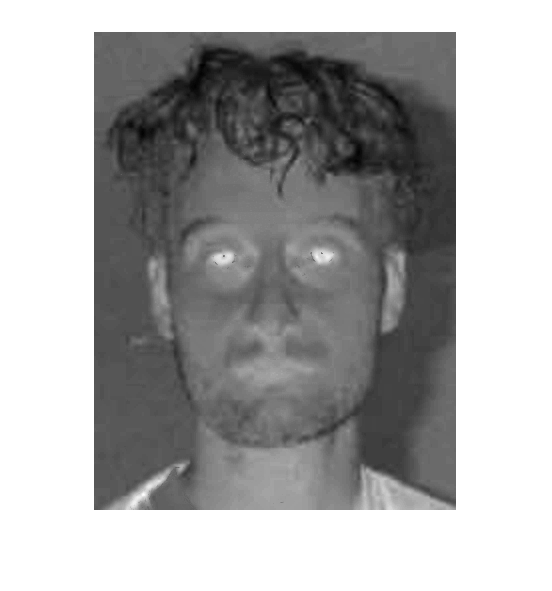

imshow(Cb.*Cb, []);

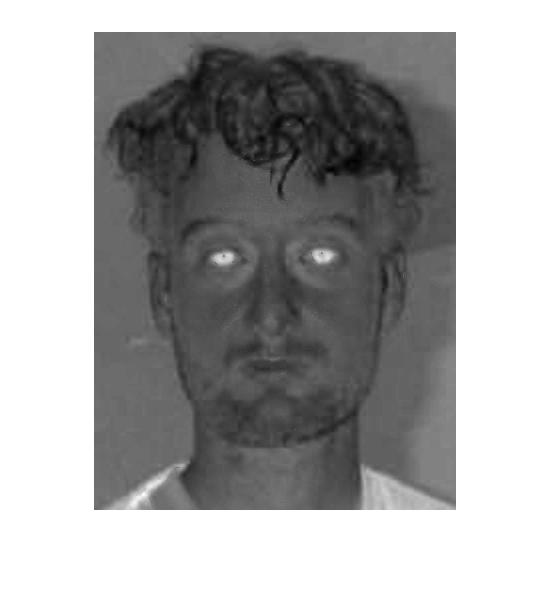


eyemapc = 1/3 .* (Cb.*Cb + Cr_c .* Cr_c + Cb ./ Cr);
imshow(eyemapc, []);

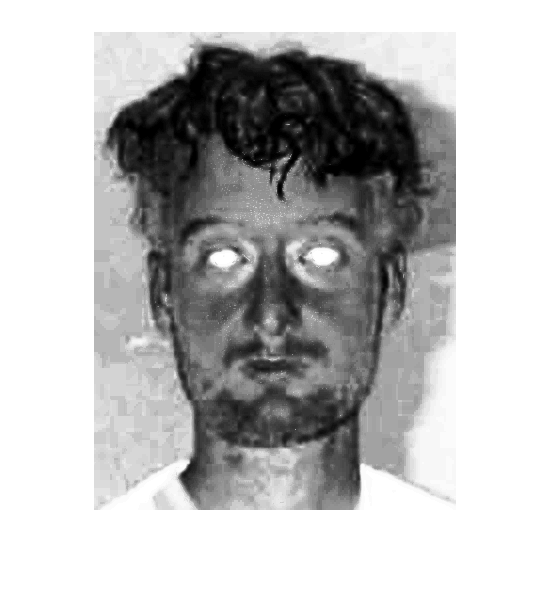

e1 = histeq(mat2gray(eyemapc));
imshow(e1);

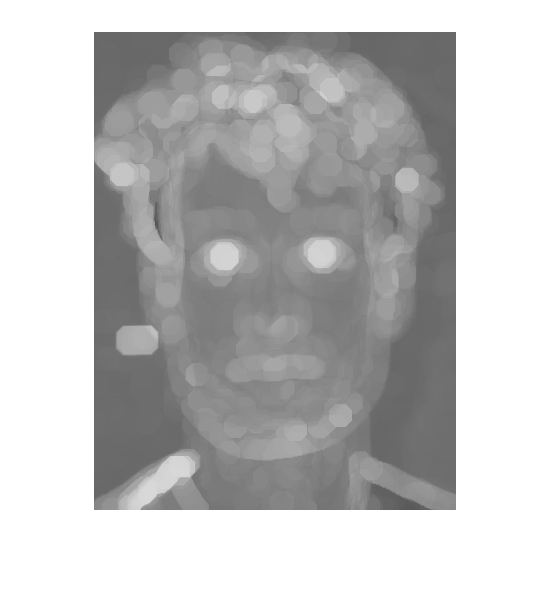


se = strel('disk', 12);
eyemapl = imdilate(Y, se) ./ (imerode(Y, se) + 1);
imshow(eyemapl);

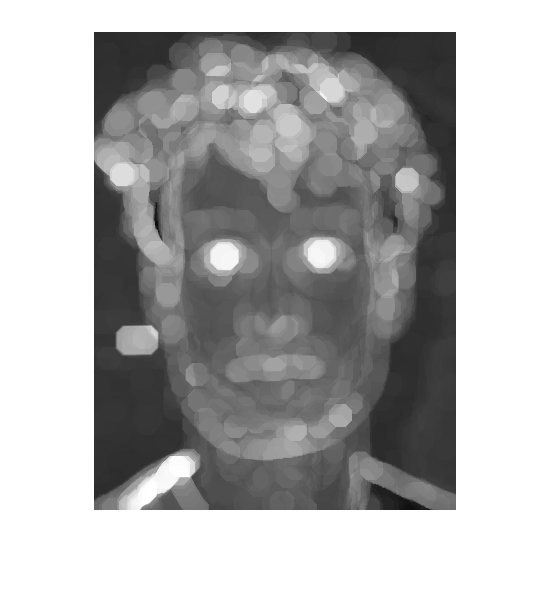

e2 = mat2gray(eyemapl);
imshow(e2);

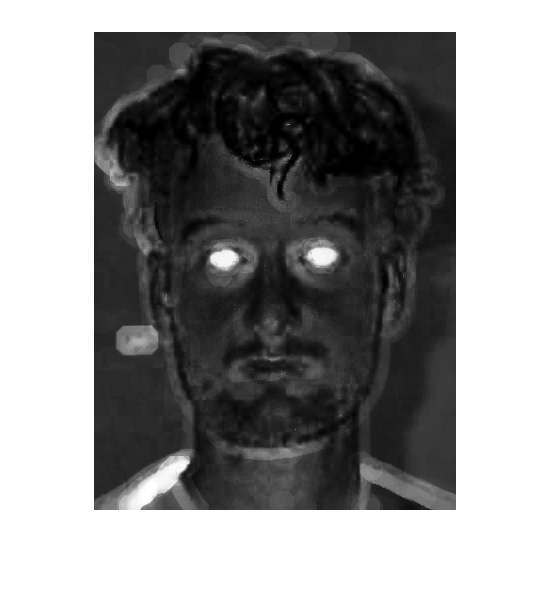



eyemap = e1 .* e2;
imshow(eyemap);

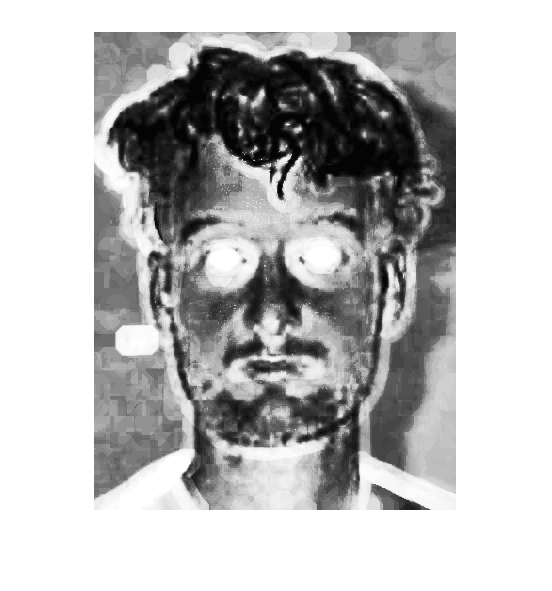

imshow(histeq(eyemap));

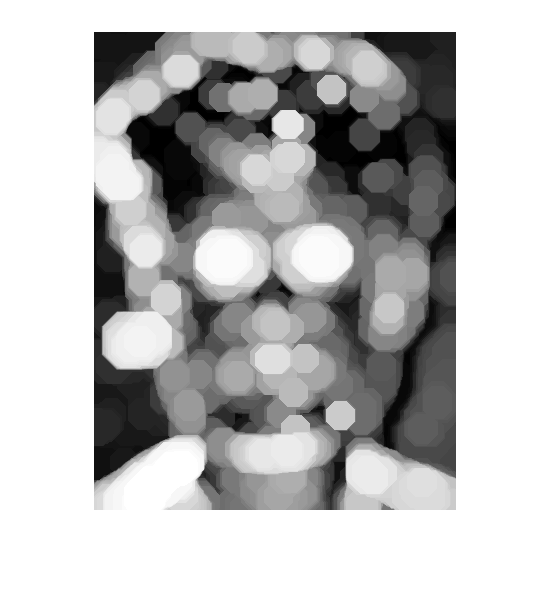

se = strel('disk', 15);
imshow(histeq(imdilate(eyemap,se)));

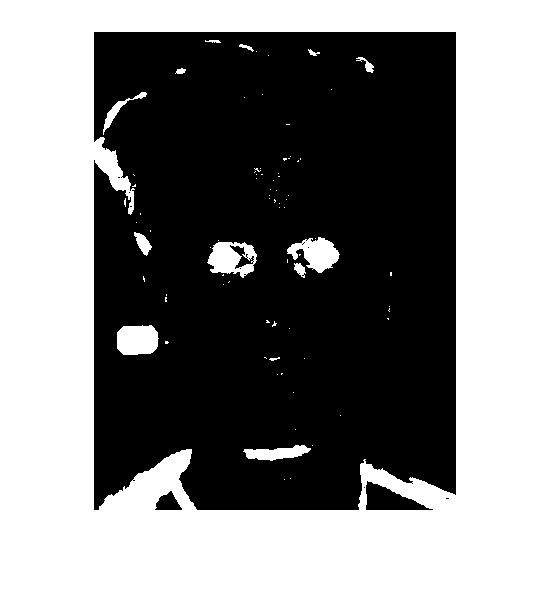



e3 = histeq(eyemap) > 0.95;
imshow(e3);

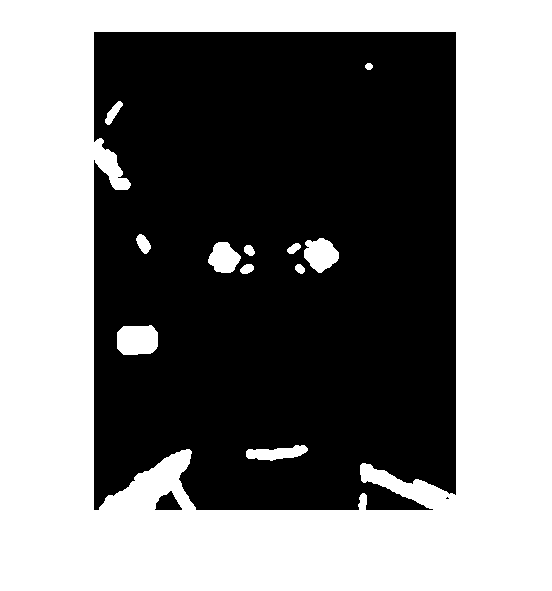

se = strel('disk', 4);
e4 = imopen(e3,se);
imshow(e4);

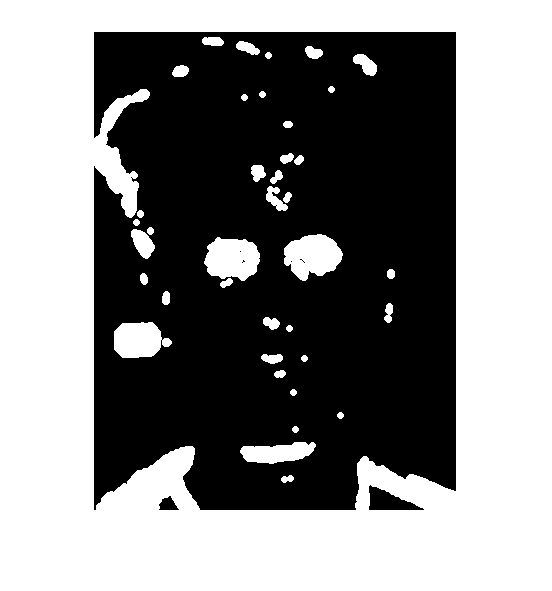

e3 = imdilate(e3, se);
imshow(e3);

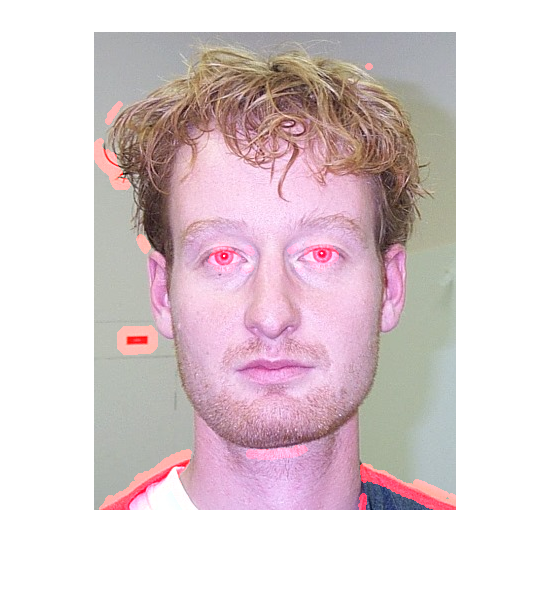


final = image;
final(:,:,1) = final(:,:,1) + e4;
figure
imshow(final)